# Example 5.15: Bayesian Estimation for a Linear Model

Note: this script reproduces Example 5.15 (Section 5.5) of **Statistics for Chemical Engineers**: prior, likelihood, and posterior of a parameter theta. Victor Z UW-Madison, 2020 bayes estimation example

clc; clear all; close all hidden; format bank;

## Prior, likelihood, and posterior

span theta values

th=linspace(-3,3);

% construct prior function p(th)
sig0=1;
th0=0;
logpth= -log(sqrt(2*pi*sig0^2)) - ((th-th0).^2)/(2*sig0);

% construct p(y|th)
sig=1;
y=2; x=1;

logpyth = -log(sqrt(2*pi*sig^2)) - ((y-th*x).^2)/(2*sig);

% construct p(th|y)
logpthy = logpyth + logpth;

## Plots

visualize prior and conditional in log space

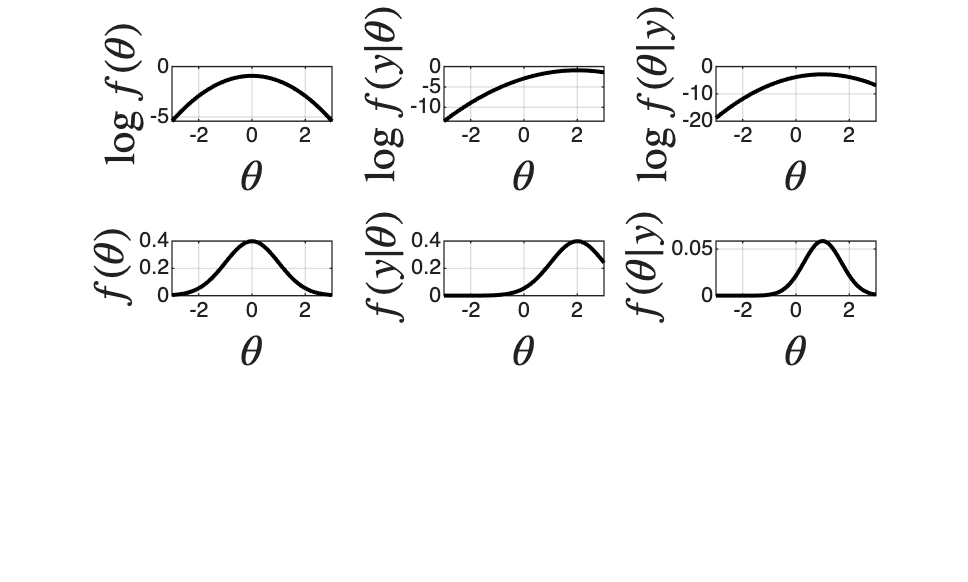

figure(1)
subplot(3,3,1)
plot(th,logpth,'black','LineWidth',1.5)
xlabel('$\theta$','Interpreter','latex','FontSize',16)
ylabel('$\log f(\theta)$','Interpreter','latex','FontSize',16)
grid on
subplot(3,3,2)
plot(th,logpyth,'black','LineWidth',1.5)
xlabel('$\theta$','Interpreter','latex','FontSize',16)
ylabel('$\log f(y|\theta)$','Interpreter','latex','FontSize',16)
grid on
subplot(3,3,3)
plot(th,logpthy,'black','LineWidth',1.5)
grid on
xlabel('$\theta$','Interpreter','latex','FontSize',16)
ylabel('$\log f(\theta|y)$','Interpreter','latex','FontSize',16)
%print -depsc ch5_bayes_log.eps

% visualize in original space
subplot(3,3,4)
plot(th,exp(logpth),'black','LineWidth',1.5)
xlabel('$\theta$','Interpreter','latex','FontSize',16)
ylabel('$f(\theta)$','Interpreter','latex','FontSize',16)
grid on
subplot(3,3,5)
plot(th,exp(logpyth),'black','LineWidth',1.5)
xlabel('$\theta$','Interpreter','latex','FontSize',16)
ylabel('$f(y|\theta)$','Interpreter','latex','FontSize',16)
grid on
subplot(3,3,6)
plot(th,exp(logpthy),'black','LineWidth',1.5)
grid on
xlabel('$\theta$','Interpreter','latex','FontSize',16)
ylabel('$f(\theta|y)$','Interpreter','latex','FontSize',16)
print -depsc ch5_bayes.eps

## Note

As in the book, the posterior blends the prior (old information) and the likelihood (new data): its most likely value, theta = 1, is a trade-off between the two.